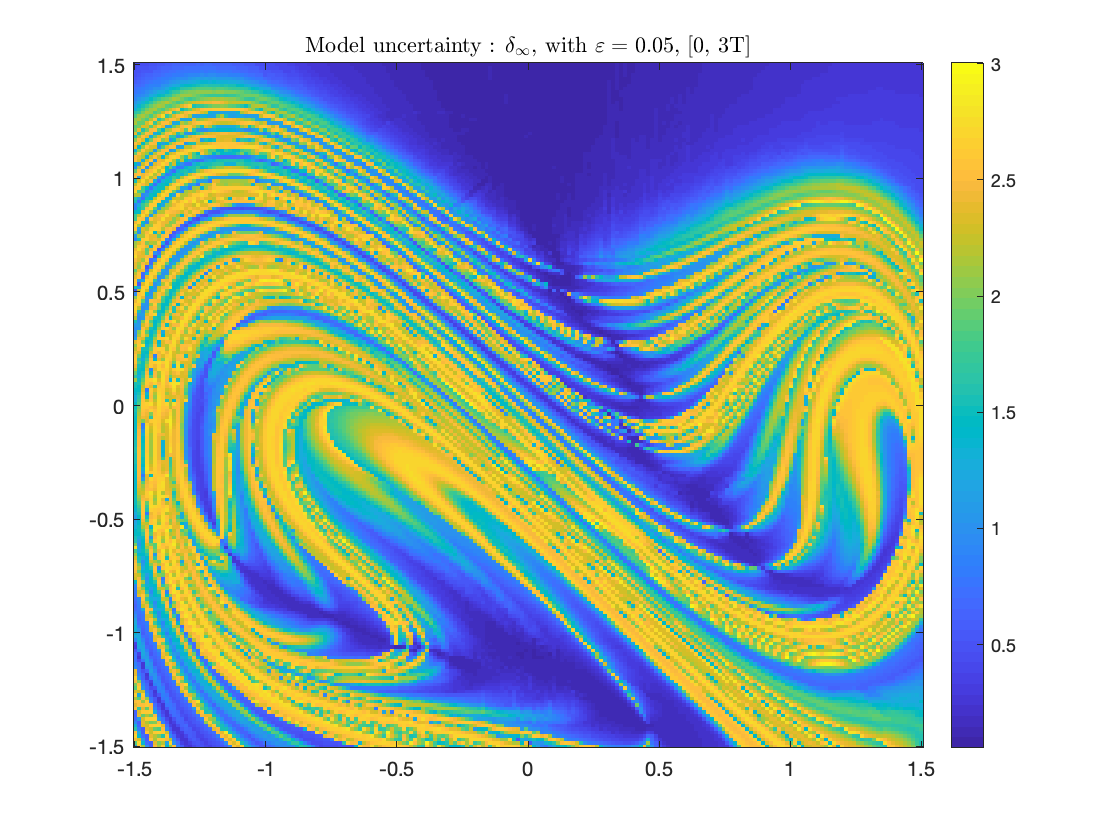

clf;
cla;
domain = [-1.5, 1.5;-1.5,1.5];
resolution = [200,200];
a = load('maxdevs______3pi_100_timedep_smallEpsilon.mat');
%disp(size(a.maxdevs));

imgs = reshape(a.maxdevs(:,end), resolution);
imagesc(domain(1,:), domain(2,:), imgs);
set(gca, 'YDir', 'normal');
colorbar;
title('Model uncertainty : $\delta_{\infty}$, with $\varepsilon = 0.05$, [0, 3T]', 'Interpreter', 'latex');

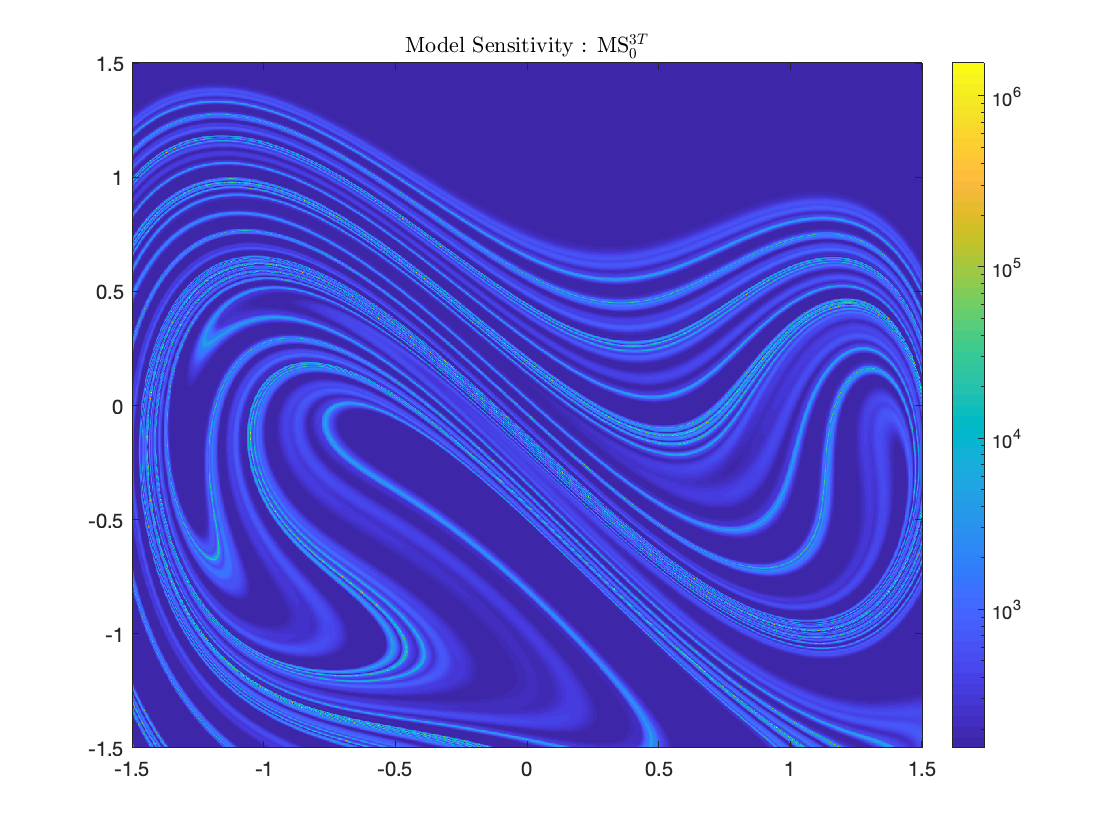


domain = [-1.5, 1.5;-1.5,1.5];
resolution = [200,200];
a = load('data/areBAndFCompatible/forw_3.mat'); 

imagesc(domain(1,:), domain(2,:), a.ftl2);
set(gca, 'YDir', 'normal');
set(gca, 'ColorScale', 'log');
colorbar;
title('Model Sensitivity : MS$_{0}^{3T}$', 'Interpreter', 'latex');

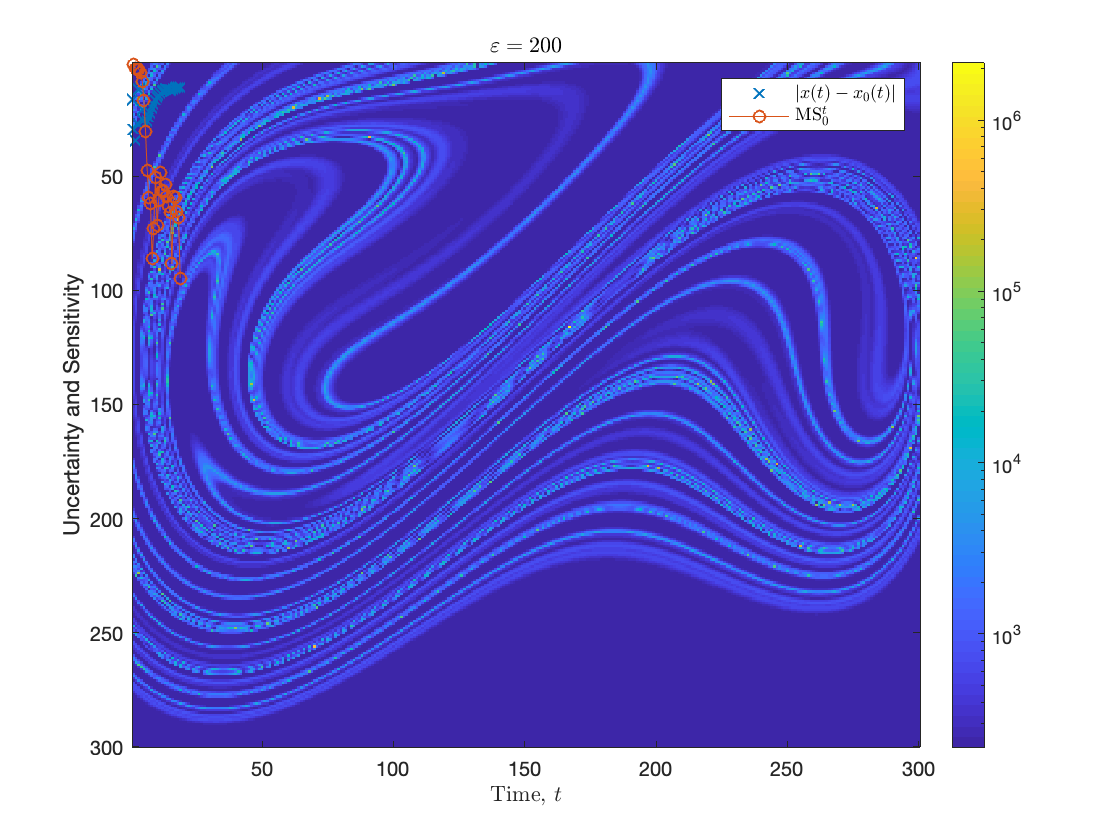


%disp(size(a.maxdevs));

a = load('data/new/SensitivityAlongTrajs____.mat');
initialPoints = initialize_ic_grid([300, 300], domain);
imagesc(reshape(a.sens(:,end), [300, 300]))
set(gca, 'ColorScale', 'log');
colorbar;
sensitvs = reshape(a.sens, [300, 300, 31]);
sensit = sensitvs(154, 220, :); 
time = linspace(0, 3*2*pi, 31);
grid = reshape(initialPoints, [300, 300, 2]);
deriv = @(t,y) d_phi(t,y,0, false);
x0 = squeeze(grid(154, 220, :));

[~,trajectoryReference] = ode45(deriv, time, x0, odeset('RelTol',1e-8));

deriv = @(t,y) d_phi(t,y,202, false);
[~,trajectory] = ode45(deriv, time, x0, odeset('RelTol',1e-8));
diff = trajectory - trajectoryReference;
distance = sqrt(diff(:,1).^2 + diff(:,2).^2);
%hold on;
%plot(trajectoryReference(), trajectoryReference(:,1), '-o');
%plot(trajectory(:,1), trajectory(:,2), '*');
figure(2);
hold on;
plot(time, distance, 'x');
plot(time, squeeze(sensit), '-o');
xlabel('Time, $t$', 'interpreter', 'latex');
ylabel('Uncertainty and Sensitivity');
legend(gca,  '$|x(t) - x_0(t)|$', 'MS$_0^t$', 'interpreter', 'latex')
title('$\varepsilon = 200$', 'interpreter', 'latex');

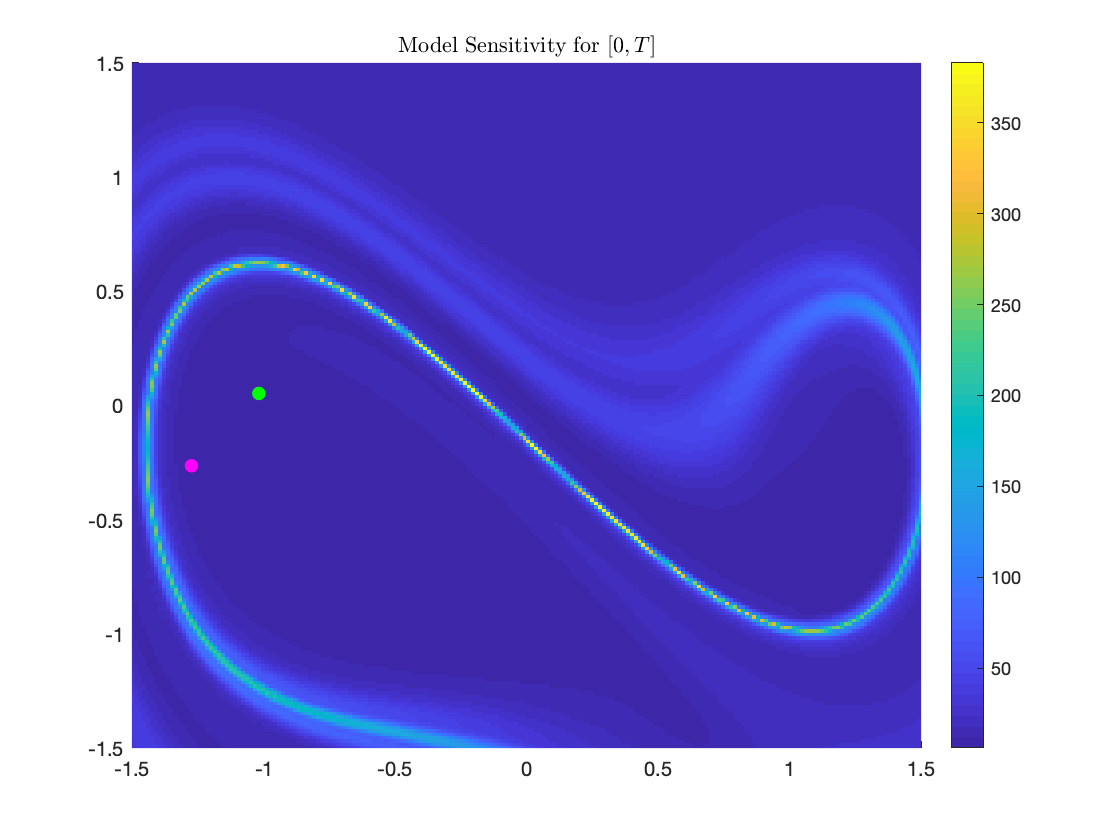


clf;
cla;
a = load('data/new/SensitivityAlongTrajs____2pi.mat');



clf;
cla;

sensitvs = reshape(a.sens, [200, 200, 51]);

clf;
cla;


mnPlaceIndex = [104, 33]; 
maxPlaceIndex = [83, 16]; 
initialPoints = initialize_ic_grid([200, 200], domain);
grid = reshape(initialPoints, [200, 200, 2]);
mnPlace = squeeze(grid(104, 33, :));
maxPlace = squeeze(grid(83, 16, :));
%critepsilonone = cr(104,33)

%critepsilontwo = cr(83,16)
hold on;
imagesc(domain(1,:), domain(2,:), reshape(a.sens(:,end), [200, 200]))
set(gca, 'Ydir', 'normal');
colorbar;
title('Model Sensitivity for $[0, T]$', 'interpreter', 'latex');
plot(mnPlace(1), mnPlace(2), '.', 'MarkerSize', 20, 'color', 'green');
plot(maxPlace(1), maxPlace(2), '.', 'MarkerSize', 20, 'color', 'Magenta');
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);

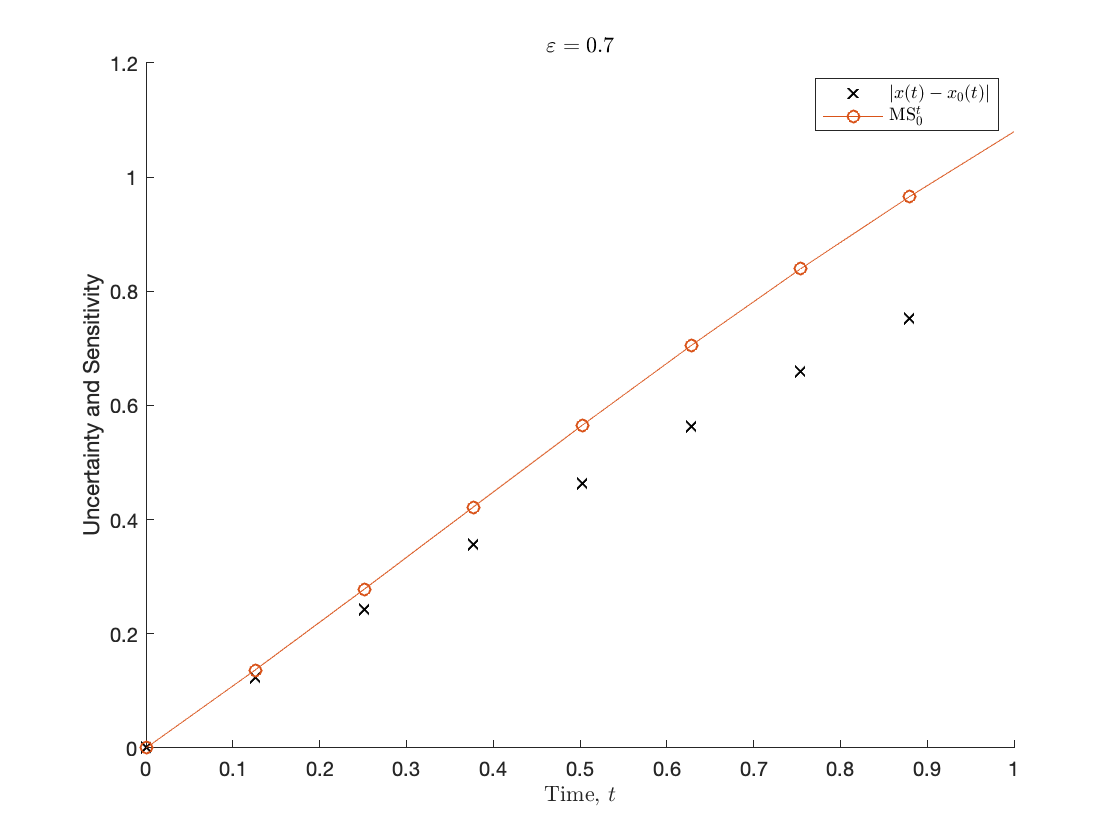



cla;
clf;


clf;
cla;

sensit = sensitvs(104,33, :); 
time = linspace(0,2*pi, 51);
deriv = @(t,y) d_phi(t,y,0, false);

[~,trajectoryReference] = ode45(deriv, time, mnPlace, odeset('RelTol',1e-8));

deriv = @(t,y) d_phi(t,y,0.1, false);
[~,trajectory] = ode45(deriv, time, mnPlace, odeset('RelTol',1e-8));
diff = trajectory - trajectoryReference;
distance = sqrt(diff(:,1).^2 + diff(:,2).^2);
figure(2);
hold on;
plot(time, distance/0.1, 'x', 'color', 'black');
plot(time, squeeze(sensit), '-o');
xlabel('Time, $t$', 'interpreter', 'latex');
ylabel('Uncertainty and Sensitivity');
legend(gca,  '$|x(t) - x_0(t)|$', 'MS$_0^t$', 'interpreter', 'latex')
title('$\varepsilon = 0.7$', 'interpreter', 'latex');
xlim([0,1])

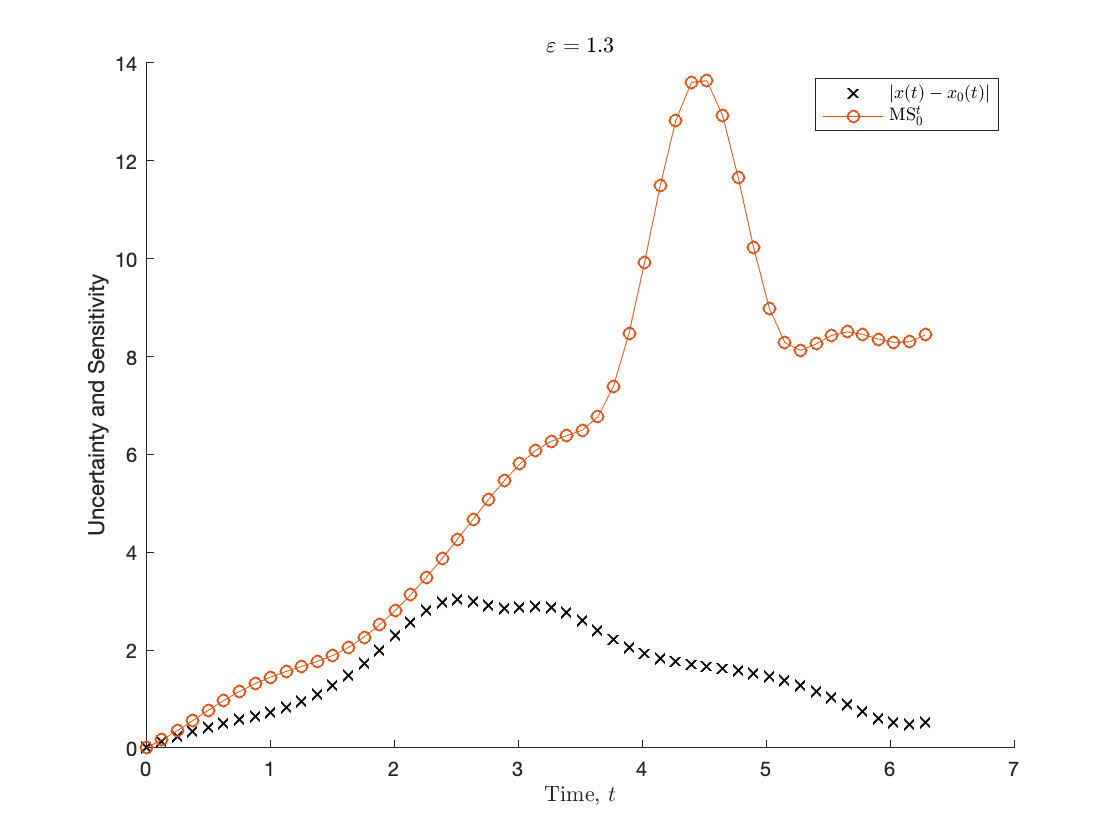


clf;
cla;



sensit = sensitvs(83,16, :); 
time = linspace(0,2*pi, 51);
deriv = @(t,y) d_phi(t,y,0, false);

[~,trajectoryReference] = ode45(deriv, time, maxPlace, odeset('RelTol',1e-8));
delta()
deriv = @(t,y) d_phi(t,y,0.9, false);
[~,trajectory] = ode45(deriv, time, maxPlace, odeset('RelTol',1e-8));
diff = trajectory - trajectoryReference;
distance = sqrt(diff(:,1).^2 + diff(:,2).^2);
figure(2);
hold on;
plot(time, distance, 'x', 'color', 'black');
plot(time, squeeze(sensit), '-o');
xlabel('Time, $t$', 'interpreter', 'latex');
ylabel('Uncertainty and Sensitivity');
legend(gca,  '$|x(t) - x_0(t)|$', 'MS$_0^t$', 'interpreter', 'latex')
title('$\varepsilon = 1.3$', 'interpreter', 'latex');

%


## When the difference between the bound and the uncertainty is positive, the inequality fails

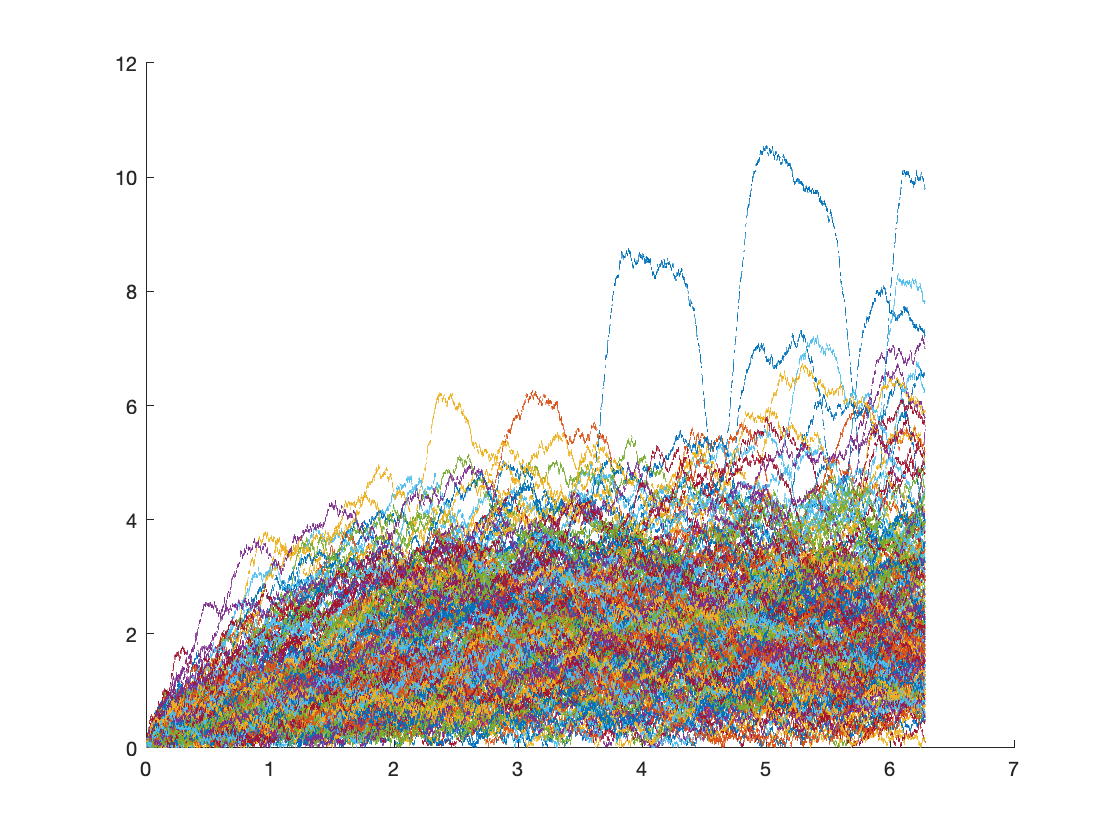




clf;
cla;
epsilon = .7;
sensit = sensitvs(104,33, :); 
time = linspace(0,2*pi, 51);
deriv = @(t,y) d_phi(t,y,0, false);


f = @(t,x) d_phi(t,x,0, false);
g = @(t,x) epsilon;
dt = 1e-5*2*pi;
time = linspace(0,2*pi, 51);
time2 = 0:dt:2*pi;

[time2,yfref] = ode45(@(t,y) d_phi(t,y,0, false),time2,mnPlace); 
aggregate = zeros(size(yfref,1),100);
hold on;

for i = 1:1000
    yf = sde_euler(f,g,time2,mnPlace);
    diff = yf-yfref;
    aggregate(:,i) = sqrt(diff(:,1).^2 + diff(:,2).^2);
    plot(time2, aggregate(:,i), '-.');
    
    %plot(t, sqrt(diff(:,1).^2+diff(:,2).^2), '.');
end

plot(time2, mean(aggregate, 2), '-', 'linewidth', 3, 'color', 'black');
plot(time, squeeze(sensit), '-o', 'linewidth', 3,'color', 'red');
xlabel('Time, $t$', 'interpreter', 'latex');
ylabel('Uncertainty and Sensitivity');
legend(gca,  '$|x(t) - x_0(t)|$', 'MS$_0^t$', 'interpreter', 'latex')
title('$\varepsilon = 0.2$', 'interpreter', 'latex');